# Single Heater: Dynamic Temperature Modeling

**Objective:** Derive a nonlinear transient model and fit a linear first order or second order system. Compare the model predictions to the transient lab data.

The first phase of the temperature control lab is to derive a dynamic model of the system with guess values for parameters. The three important elements for a control loop are the measurement device (thermistor temperature sensor), an actuator (transistor), and capability to perform computerized control (USB interface). At maximum output the transistor dissipates 1 W of power at 100% heater output. The mass of the transistor and heat sink with fins is 4 gm.

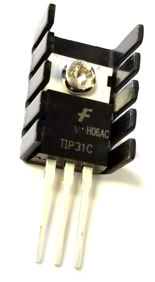 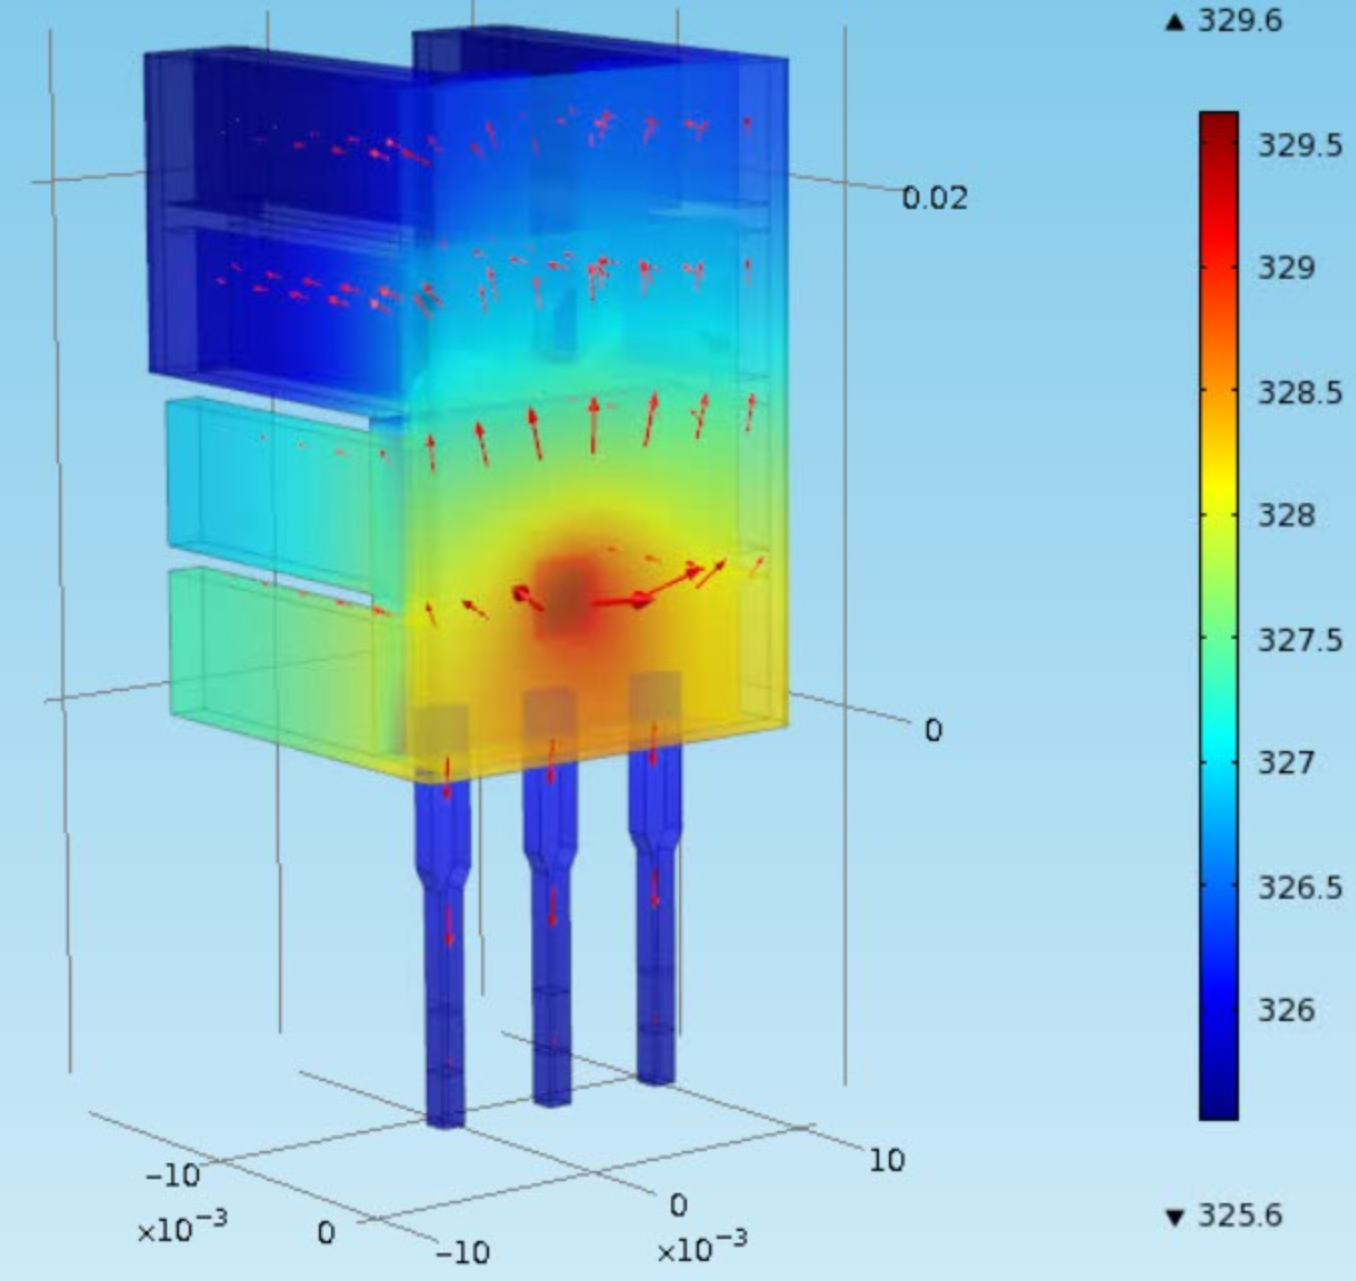

Steel has a heat capacity of 500 $J/{kg K}$. The surface area of the heater and sensor is about 12 $cm^2$. A convective heat transfer coefficient for quiescent air is approximately 10 $W/{m^2K}$. The heat generated by the transistor transfers away from the device primarily by convection but radiative heat transfer may also be a contributing factor. The radiative heat transfer can be included in the model to determine what fraction of heat is lost by convection and heat radiation. Heat transfer is improved with a thermal coupling (white epoxy) that connects the two components.


$$\matrix{

\textbf{Component} & \textbf{Value}\cr
\text{Initial Temperature}(T_0) & 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Ambient Temperature}(T_\infty)& 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Heater Output}(Q) & 0-100\%\cr
\text{Heater Factor}(\alpha) & 0.0123 \text{ W/(\% heater)}\cr
\text{Heat Capacity}(C_p) & 500 \text{ J/kg-K}\cr
\text{Surface Area Not Between Heaters}(A) & 1.2*10^{-3}\text{ m}^2(10\text{ cm})\cr
\text{Mass}(m) & 0.004\text{ kg }(4 \text{ gm })\cr
\text{Conduction Time Constant}(\tau) & 20.3 \text{ sec}\cr
\text{Overall Heat Transfer Coefficient} (U) & 4.7 \text{ W/m}^2\text{-K}\cr
\text{Emissivity}(\epsilon) & 0.9\cr
\text{Stefan Boltzmann Constant }(\sigma) & 5.67*10^{-8} \text{ W/m}^2\text{-K}^4\cr
}$$


Create a dynamic model of the dynamic response between input power to the transistor and the temperature sensed by the thermistor. Use an energy balance to start the derivation.


$$m\,c_p\frac{dT}{dt} = \sum \dot h_{in} - \sum \dot h_{out} + Q$$


Expand or simplify terms that are needed for this application. The full energy balance includes convection and radiation terms.


$$m\,c_p\frac{dT}{dt} = U\,A\,\left(T_\infty-T\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T^4\right) + \alpha Q$$


where $m$ is the mass, $c_p$ is the heat capacity, $T$ is the temperature, $U$ is the heat transfer coefficient, $A$ is the area, $T_\infty$ is the ambient temperature, $\epsilon=0.9$ is the emissivity, $\sigma = 5.67x10-8 W/{m^2 K^4}$ is the Stefan-Boltzmann constant, and $Q$ is the percentage heater output. The parameter $ \alpha$ is a factor that relates heater output (0-100%) to power dissipated by the transistor in Watts. Use this equation to develop a dynamic simulation of the temperature response due to an impulse (off, on, off) in the heater output. Leave the heater on for sufficient time to observe nearly steady state conditions.

### **Single Heater Model**

Investigate issues such as whether radiative heat transfer is significant, is the temperature response inherently first order or higher order, and what values of uncertain parameters in the physics based model help the predicted temperature agree with the data.

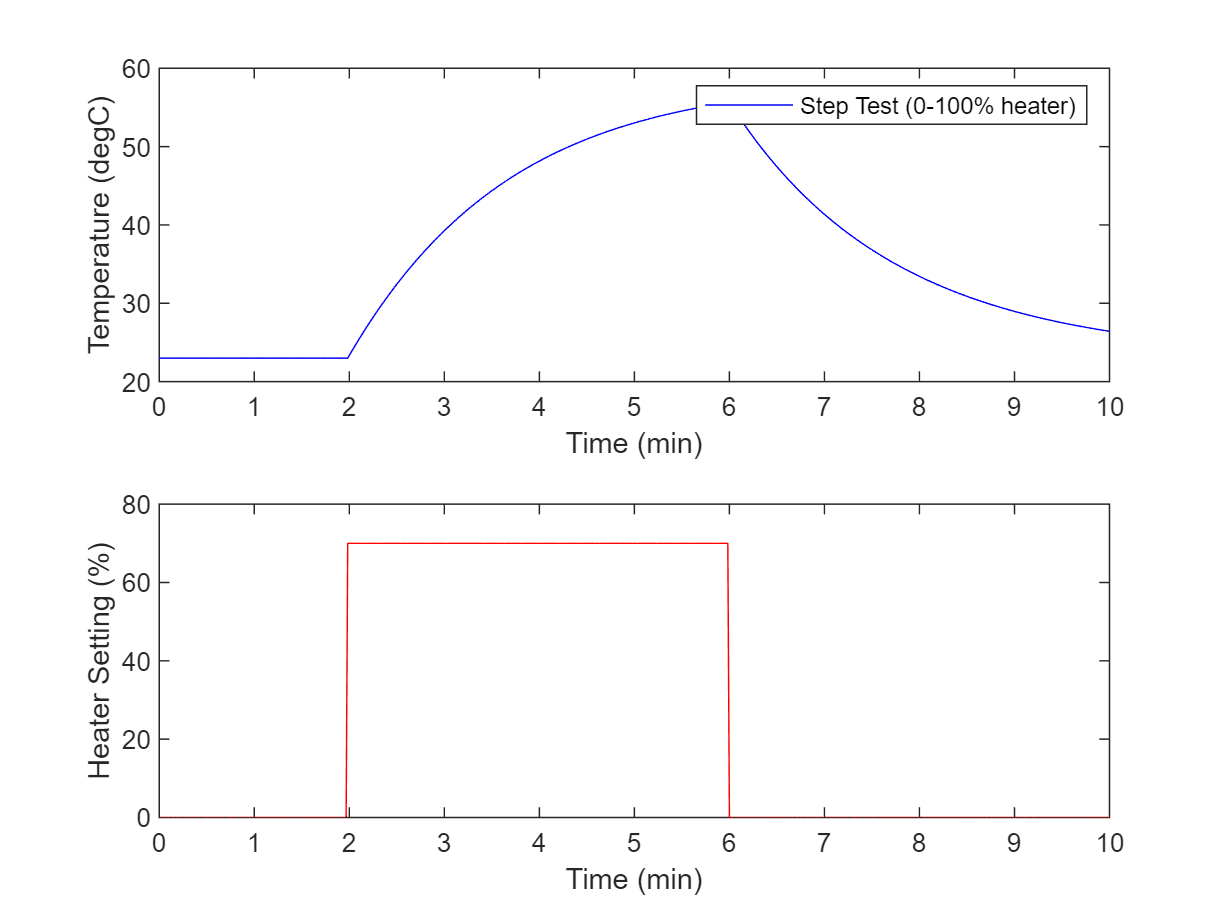

clear all; close all; clc

n = 60*10+1;  % Number of second time points (10min)
Q_ = zeros(1,n);% Heater setting 
Q_(120:360) = 70;
T1K_ = ones(1,n) * (273.15+23.0);
time = linspace(0,n-1,n); % Time vector
for i =1:n-1 
    [~,TK] = ode23(@(t,x)heat(t,x,Q_(i)),[time(i), time(i+1)],T1K_(i)); % Integrate ODE
    T1K_(i+1) = TK(end);
end
TC_ = T1K_ - 273.15;
% Plot results
figure(1)
subplot(2,1,1)
plot(time/60.0,TC_,'b-')
ylabel('Temperature (degC)')
xlabel('Time (min)')
legend('Step Test (0-100% heater)')
subplot(2,1,2)
plot(time/60.0,Q_,'r-')
ylabel('Heater Setting (%)')
xlabel('Time (min)')

## **Single Heater Model + Arduino TCLab**

Now, use the TCLab to compare the energy balance model to data from the TCLab

T1_ = zeros(1,n)  % create storage for temperatures

T1_ =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


time_tclab = zeros(1,n)

time_tclab =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


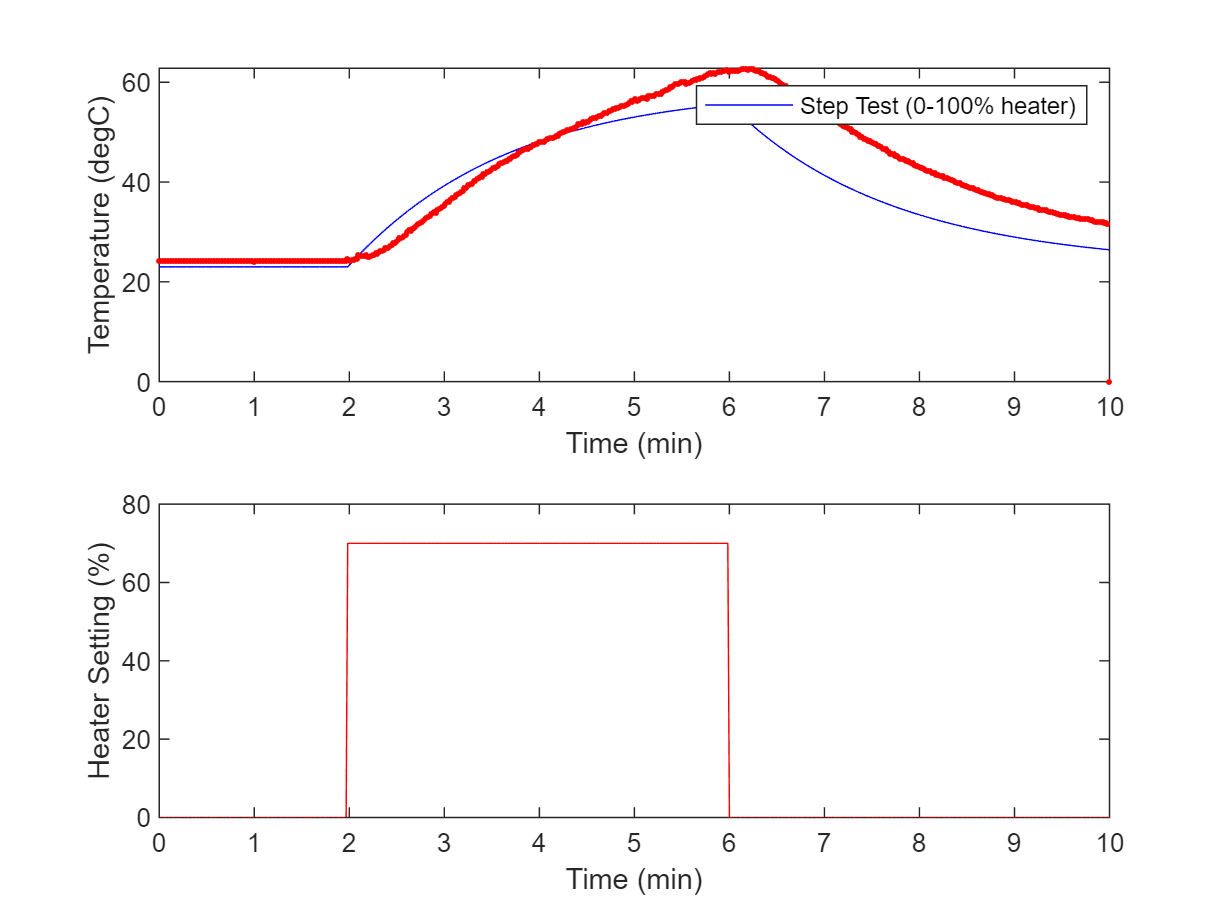


lab=tclab;  % Connect to TCLab
tic;        % Start Timer
for i=1:n-1
    time_tclab(i) = toc;
    lab.Q1(Q_(i));         % Set Heater
    T1_(i) = lab.T1;       % Record temperature
    pause(1-mod(toc,1));
end

% Plot results
figure(1)
subplot(2,1,1)
plot(time/60.0,TC_,'b-', 'DisplayName','Energy Balance')
hold on
plot(time/60, T1_, 'r.', 'DisplayName','TCLab')
hold off
ylabel('Temperature (degC)')
xlabel('Time (min)')
legend('Step Test (0-100% heater)')
subplot(2,1,2)
plot(time/60.0,Q_,'r-')
ylabel('Heater Setting (%)')
xlabel('Time (min)')

## Solution Videos

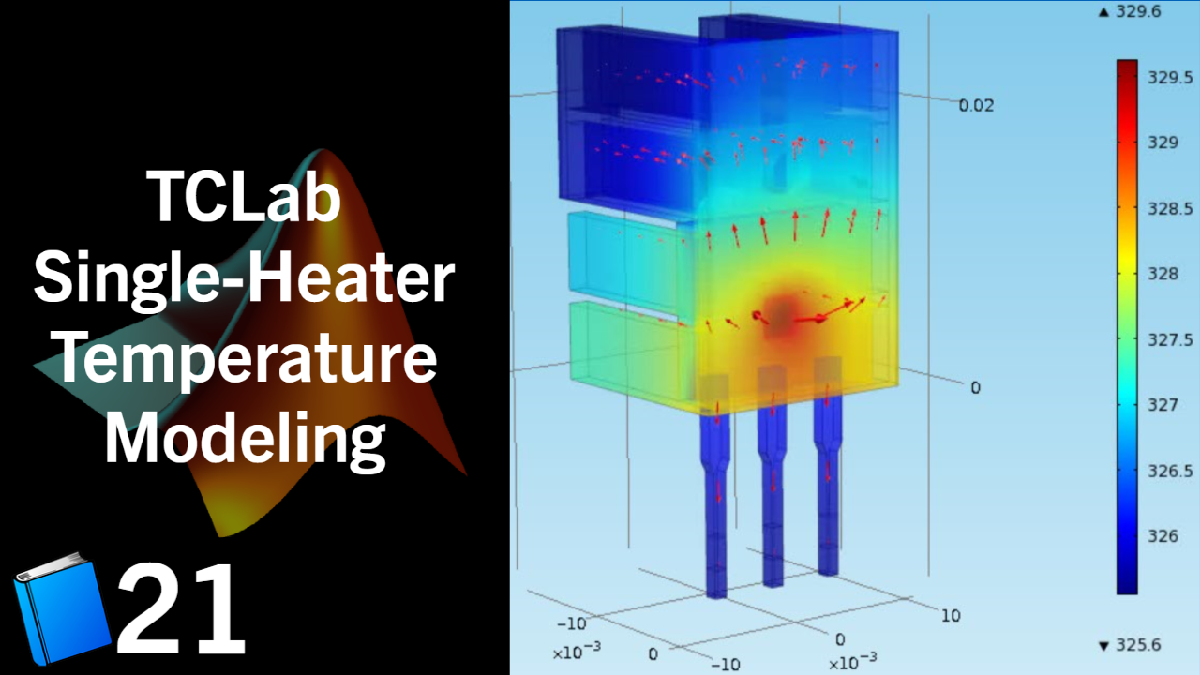

### [View Solution Video](https://youtu.be/fWFKsV7egKY)

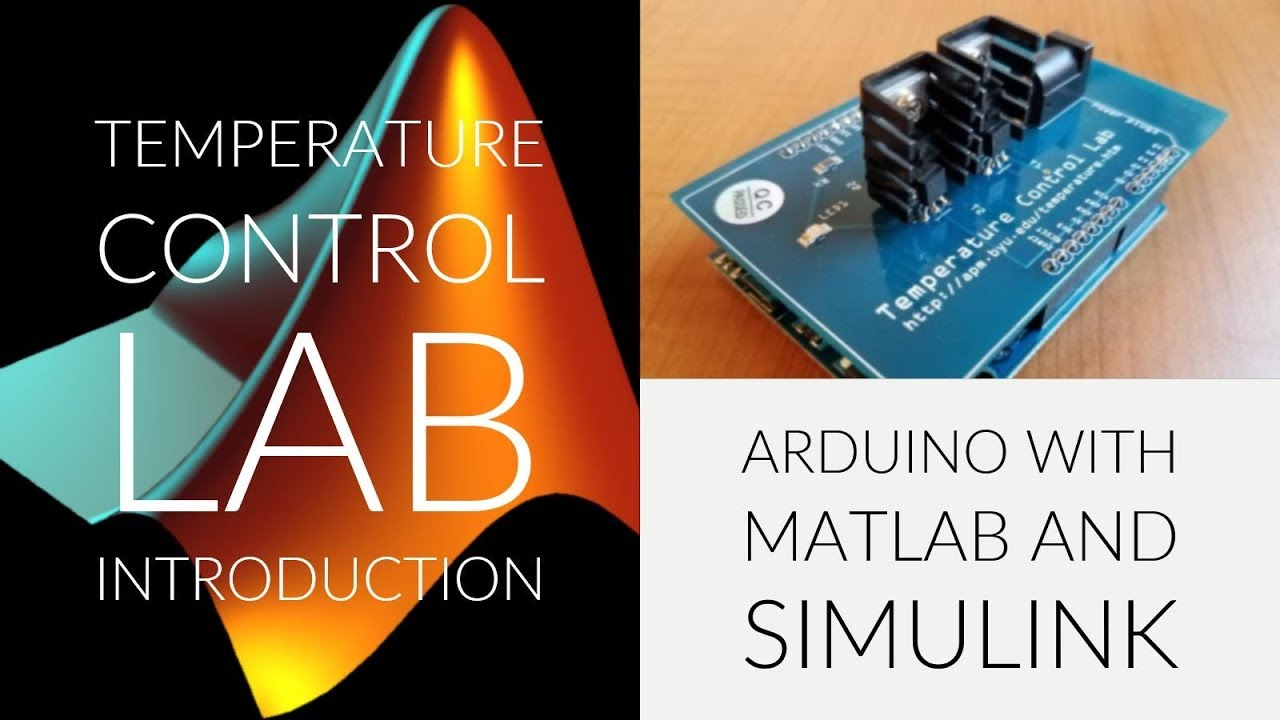

### [View Lecture](https://www.youtube.com/watch?v=kyYnLFy9OMc)

MATLAB and Simulink source is available below.

 [**Download MATLAB TCLab Files for Single Heater**](https://apmonitor.com/pdc/uploads/Main/tclab_matlab_siso.zip)

 [**Download Simulink TCLab Files for Single Heater**](https://apmonitor.com/pdc/uploads/Main/tclab_simulink_siso.zip)

The files include a linear (**FOPDT**) model, a nonlinear model, and the temperature control lab interface to run the three in comparison.

The Arduino transient temperature responds similarly to the energy balance solution. Just like the physical system, this simulated system responds to changes in the heater.

function dTdt = heat(~,x,Q)
    % Parameters
    Ta = 23 + 273.15;   % K
    U = 10.0;           % W/m^2-K
    m = 4.0/1000.0;     % kg
    Cp = 0.5 * 1000.0;  % J/kg-K    
    A = 12.0 / 100.0^2; % Area in m^2
    alpha = 0.01;       % W / % heater
    eps = 0.9;          % Emissivity
    sigma = 5.67e-8;    % Stefan-Boltzman

    % Temperature State
    T = x(1);

    % Nonlinear Energy Balance
    dTdt = (1.0/(m*Cp))*(U*A*(Ta-T) ...
            + eps * sigma * A * (Ta^4 - T^4) ...
            + alpha*Q);
end
